# Introducing ISET3d calculations

Renders a scene containing a sphere to illustrate the basic read, edit, write cycle.

**See also:**

    t_piIntro_*, piRecipeDefault, @recipe

## Initialize ISET and Docker

Start up ISET and check that docker is configured 

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the recipe

thisR = piRecipeDefault('scene name','sphere');

Read 1 materials and 0 textures..


The recipe has many fields that control the scene properties how it is rendered.  We simply list them here.  A lot of this wiki describes how to set and get properties from the many slots ISET3d recipe slots.

thisR

thisR =   recipe with properties:

                camera: [1×1 struct]
               sampler: [1×1 struct]
                  film: [1×1 struct]
                filter: []
            integrator: [1×1 struct]
              renderer: []
                lookAt: [1×1 struct]
                 scale: [0×3 double]
                 world: {'WorldBegin'}
                lights: []
        transformTimes: []
             inputFile: '/Users/wandell/Documents/MATLAB/iset3d-v4/data/V4/sphere/sphere.pbrt'
            outputFile: '/Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/sphere.pbrt'
          renderedFile: ''
               version: 4
             materials: [1×1 struct]
              textures: [1×1 struct]
                assets: [1×1 tree]
              exporter: 'PARSE'
                 media: []
              metadata: [1×1 struct]
             recipeVer: 2
    hasActiveTransform: 0
               verbose: 2


## Edit the recipe

For example, we can place a point light in the sphere scene.  Without a light, the scene will appear black!

% The pinhole case is puzzling to us.  We need to look into it.
%{
thisLight = piLightCreate('point','type','point','cameracoordinate', true);
thisR.set('light',thisLight, 'add');
thisR.set('light',thisLight.name,'specscale',0.5);
thisR.set('light',thisLight.name,'spd',[0.5 0.5 0.2]);
%}
% {
thisLight = piLightCreate('distant','type','distant',  'spd', 5000,  'cameracoordinate', true);
thisR.set('light',thisLight, 'add');
%}

We can also set rendering properties.

thisR.set('film resolution',[192 192]);
thisR.set('rays per pixel',128);
thisR.set('n bounces',1); % Number of bounces
thisR.set('render type', {'radiance', 'depth'});

## Write the recipe, render it, and show it

piWrite(thisR);

In this example, we use a pinhole camera, so that we are effectively rendering the scene radiance.  If we include a lens, we would be rendering an optical image.

[scene, result] = piRender(thisR);

 Rsync Put: rsync -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/
Pushed scene to remote in:   0.30
Render: docker --context remote-mux exec -it  pbrt-gpu-wandell19337 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt"
Successfuly rendered remotely in:   2.08
 Rsync Pull: rsync -r wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/renderings
Retrieved output in:   0.33
pbrt version 4 (built May  8 2022 at 01:12:42)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.

Rendering: [                                                                                        ] 
R

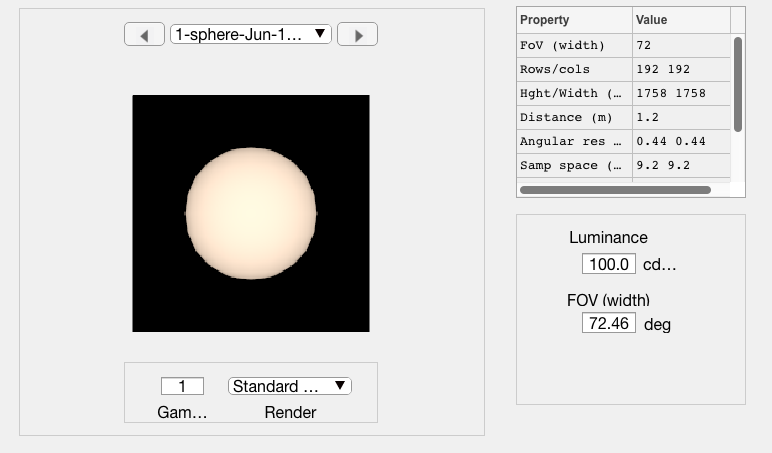

sceneWindow(scene);

## By default, piRender computes the scene or oi depth map

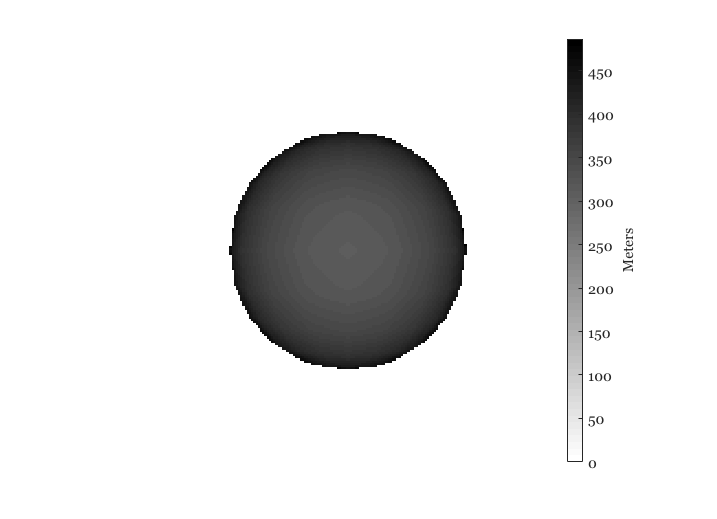

scenePlot(scene,'depth map');

## Change the light to a bluish light

You can edit the lights this way, adding a light which is more blue and distant 

% Remove the light we added
thisR.set('light',thisLight.name, 'delete');

% Create a new version with a different color temperature
thisLight = piLightCreate('distant','type','distant',  'spd', 9000,  'cameracoordinate', true);
thisR.set('light',thisLight, 'add');

This is an efficient way to Write, Render and Show without the separate calls.

 Rsync Put: rsync -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/
Pushed scene to remote in:   0.32
Render: docker --context remote-mux exec -it  pbrt-gpu-wandell19337 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt"
Successfuly rendered remotely in:   2.26
 Rsync Pull: rsync -r wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/renderings
Retrieved output in:   0.33
pbrt version 4 (built May  8 2022 at 01:12:42)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.

Rendering: [                                                                                        ] 
R

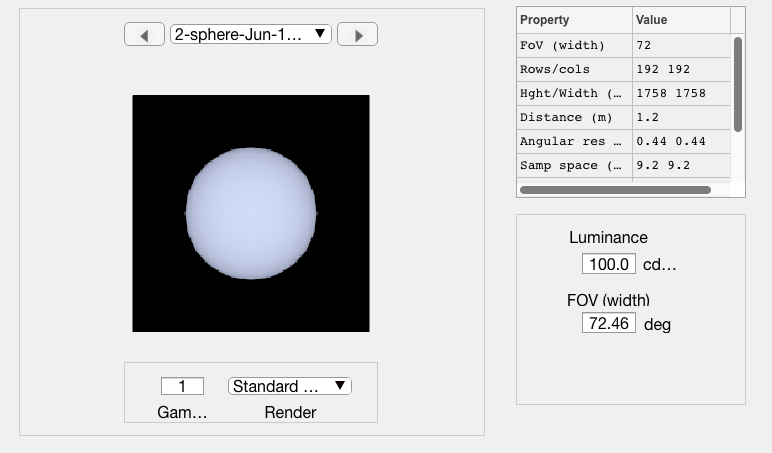

piWRS(thisR);

## Read an  FBX file and write it as PBRT

% FBX is converted into PBRT
fname = fullfile(piRootPath,'data','V4','teapot-set','TeaTime-converted.pbrt');
 
thisR  = piRead(fname);

Read 6 materials and 1 textures..


Convert scene unit from centimeter to meter

thisR.set('film resolution',[600 600]/2);
thisR.set('rays per pixel',32);

Set the render type.

One type is radiance, and here are the others

**rTypes = {'radiance','depth','both','all','coordinates','material','instance', 'illuminant','illuminantonly'};**

thisR.set('film render type',{'radiance','depth'});

%% move object
thisR.set('asset','Cylinder.001_B','world translation',[0.2 0 0]);

thisR.show('objects');

                                     material            positions (m)           sizes (m)   
                                 ________________    _____________________    _______________

    0006ID_001_Cylinder.001_O    {'Stone'       }    {'6.39 5.47 16.50'  }    {'NaN NaN NaN'}
    0008ID_002_Cylinder.001_O    {'Rubber'      }    {'6.39 5.47 16.50'  }    {'NaN NaN NaN'}
    0010ID_003_Cylinder.001_O    {'Porcelain'   }    {'6.39 5.47 16.50'  }    {'NaN NaN NaN'}
    0012ID_004_Cylinder.001_O    {'Wood'        }    {'6.59 5.47 16.50'  }    {'NaN NaN NaN'}
    0015ID_001_Cylinder.004_O    {'Stone'       }    {'-8.18 5.47 11.67' }    {'NaN NaN NaN'}
    0017ID_002_Cylinder.004_O    {'Rubber'      }    {'-8.18 5.47 11.67' }    {'NaN NaN NaN'}
    0019ID_003_Cylinder.004_O

## Add a light

 Rsync Put: rsync -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/TeaTime-converted/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/TeaTime-converted/
Pushed scene to remote in:   0.41
Render: docker --context remote-mux exec -it  pbrt-gpu-wandell19337 sh -c "cd /iset/iset3d-v4/local/TeaTime-converted && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/TeaTime-converted.exr TeaTime-converted.pbrt"
Successfuly rendered remotely in:   3.10
 Rsync Pull: rsync -r wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/TeaTime-converted/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/TeaTime-converted/renderings
Retrieved output in:   0.36
pbrt version 4 (built May  8 2022 at 01:12:42)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.

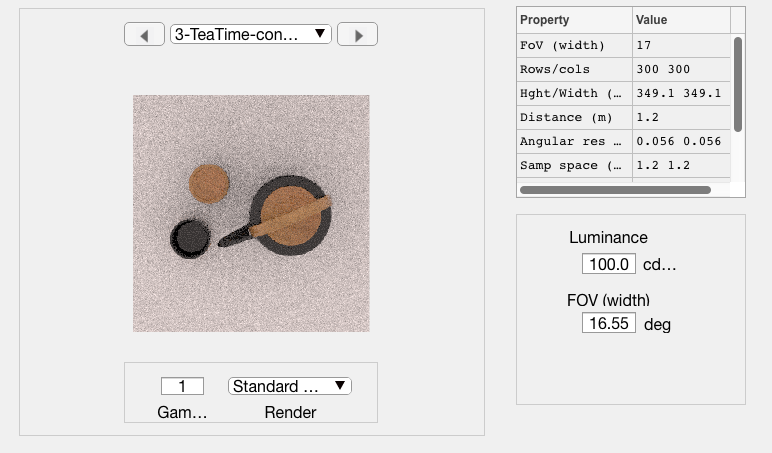

piLightDelete(thisR, 'all'); 
lightName = 'new light';
newLight = piLightCreate(lightName,...
                        'type','infinite',...
                        'spd',[0.4 0.3 0.3],...
                        'specscale',1);
thisR.set('light', newLight, 'add');

% Render and return the scene
scene = piWRS(thisR);

Show the geometry

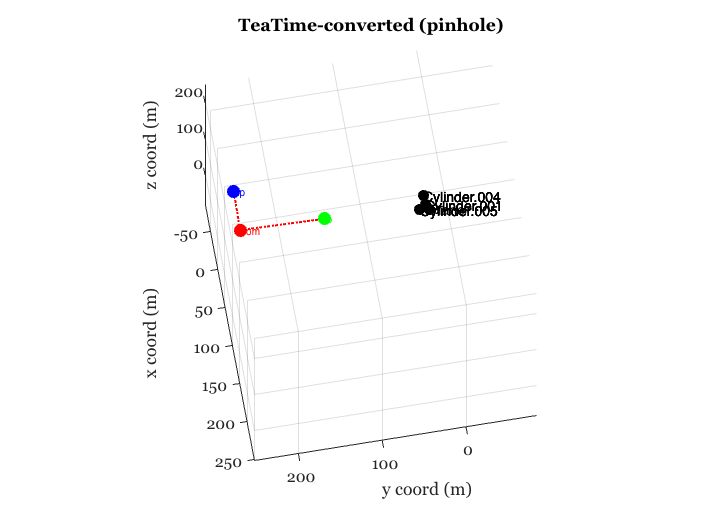

piAssetGeometry(thisR);view(-80,-65);